# Lab - Boundary value problems 2

**Topics: **finite-difference method for linear equations, finite-difference method for non-linear equations

## Water table height

clear, clc

Given: $K\bar{h} \;\frac{d^2 h}{{\textrm{dx}}^2 }+N=0$

Solve for the height of the water table for x = 0 to 1000 m where h(0)=10 m and h(1000)=5 m. Use the following parameters: K=1 m/d and N=0.0001 m/d. Use the average of the boundary conditions as the average height ($\bar{h}$). $\Delta x=200\;m$

### Set up variables

x0 = 0;
xf = 1000;
N = .0001;
K = 1;
H0 = 10;
Hf = 5;
hBar = (H0 + Hf)/2;
dx = 200;

### **Analytical solution**


$$K\bar{h} \;\frac{d^2 h}{{\textrm{dx}}^2 }+N=0$$


syms h(x)
Dh = diff(h);
ode = K*hBar*diff(h, x, 2)+N == 0;

cond1 = h(x0) == H0;
cond2 = h(xf) == Hf;
conds=[cond1 cond2];
solution(x)=dsolve(ode, conds)

$$solution(x) = -\frac{x^{2}}{150000}+\frac{x}{600}+10$$

### Set up system


$$h_{i-1} -2h_i +h_{i+1} =-\frac{N\Delta x^2 }{K\bar{h} }$$


C = (-N*dx^2)/(K*hBar);


$$\begin{array}{l}
-2h_1 +h_2 =C-h_0 \\
h_1 -2h_2 +h_3 =C\\
h_2 -2h_2 +h_3 =C\\
h_3 -2h_4 =C-h_5 
\end{array}$$


% % Direct Method: Painful for smaller step sizes
% A = [-2 1 0 0
%     1 -2 1 0
%     0 1 -2 1
%     0 0 1 -2];
% b = [C-H0; C; C; C-Hf];

% Diagonal Method
n = (xf-x0)/dx-1;
A = diag(-2*ones(1,n)) + diag(ones(1,n-1),1) + diag(ones(1,n-1),-1);
b = C*ones(n,1);
b(1) = b(1)-H0;
b(end) = b(end)-Hf;

### Solve

hvals = (A\b)';
hvals = [H0 hvals Hf];
xvals = x0:dx:xf;

### Plot

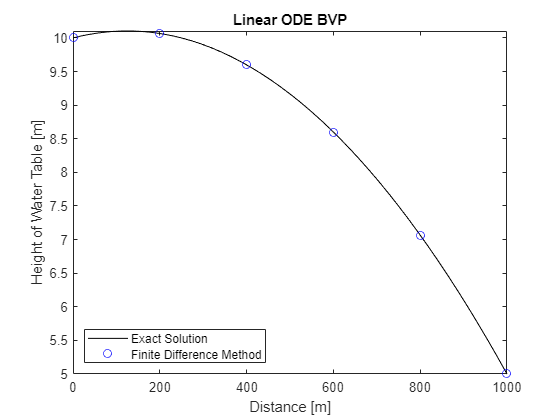

figure()
fplot(solution, [x0 xf], "k")
hold on
plot(xvals, hvals, "bo")
hold off
xlabel("Distance [m]")
ylabel("Height of Water Table [m]")
legend("Exact Solution", "Finite Difference Method", "location", "southwest")
title("Linear ODE BVP")

## Non-linear BVP

clear, clc

Given: $\frac{d^2 y}{{\textrm{dx}}^2 }=4+0\ldotp 25x^3 -0\ldotp 125y\;\frac{\textrm{dy}}{\textrm{dx}}$

Solve for y in the range of $1\le x\le 3$ with $\Delta x=0\ldotp 5$

where $y\left(1\right)=17$ and $y\left(3\right)=\frac{43}{3}$

### Set up variables

x0 = 1;
xf = 3;
y0 = 17;
yf = 43/3;
dx = .5;
x_finite = x0:dx:xf;
n = length(x_finite);
Y_finite = linspace(y0,yf,n)

Y_finite =    17.0000   16.3333   15.6667   15.0000   14.3333


### **Analytical solution**


$$y\left(x\right)=x^2 +\frac{16}{x}$$


x_exact = linspace(x0, xf);
y_exact = x_exact.^2 + 16./x_exact;

### Solution

Y_finite = yiter(x_finite, Y_finite, dx)

Y_finite =    17.0000   15.3876   14.3489   13.3492   14.3333


itercount = 1;
while(1)
    itercount = itercount + 1;
    Y_old = Y_finite;
    Y_finite = yiter(x_finite, Y_finite, dx);
    ea = max(abs((Y_finite-Y_old)./Y_finite)*100);
    if ea < 0.001
        break
    end
end

Y_finite, itercount

Y_finite =    17.0000   12.8509   11.9433   12.6214   14.3333


itercount = 13

### Plot y

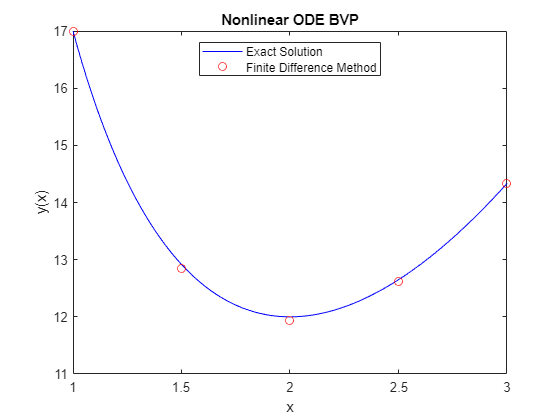

figure()
plot(x_exact, y_exact, "-b", x_finite, Y_finite, "ro")
xlabel("x")
ylabel("y(x)")
legend("Exact Solution", "Finite Difference Method", "location", "north")
title("Nonlinear ODE BVP")

## Helper functions


$$y_i =-\frac{\Delta x^2 }{2}\left(4+\frac{x^3 }{4}-\frac{y_i \left(y_{i+1} -y_{i-1} \right)}{16\Delta x}\right)+\frac{y_{i+1} +y_{i-1} }{2}$$


function y = yiter(x, y, dx)
    n = length(y);
    
    for i = 2:n-1
        y(i) = -(dx^2)/2*(4 + (x(i)^3)/4 - (y(i)*(y(i+1)-y(i-1)))/(16*dx)) + (y(i+1)+y(i-1))/2;
    end
end